clear all; clc

% Data settings
Speed = 20;
RPM = 10;

% Aircraft Geometry
S = 0.03469846; %m^2 (1578 ft^2/65^2)
Cmac = 0.06495; %m (13.85ft/65)

% Atmospheric Conditions
rho = 1.21; %kg/m^3
DynVisc = 1.81*10^(-5); %kg/ms

% Reynolds
Re = rho*Speed*Cmac / DynVisc

Re = 8.6839e+04

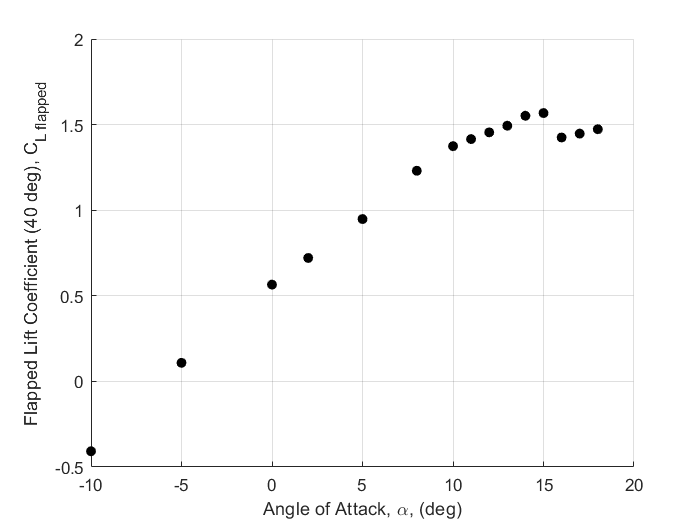


AoA = [-10, -5, 0, 2, 5, 8, 10:18];

for i = 1:length(AoA)

    thisAoA = AoA(i);

    % Get file names
    fileName = "u_"+ string(Speed) + "_a" + string(thisAoA) + "_r" + string(RPM)  + "_F_calibrated" + ".mat";
        
    x = load (fileName);
    
    % Get CL, CD, AoA
    CL(i) = (x.Fz*cosd(thisAoA) + x.Fx*sind(thisAoA)) / (0.5*rho*x.V^2*S);
    CD(i) = (x.Fz*sind(thisAoA) - x.Fx*cosd(thisAoA)) / (0.5*rho*x.V^2*S);
    Cm(i) = x.Ty / (0.5*rho*x.V^2*S*Cmac);
    
    clear x;
end

% Lift Curve graph
figure
scatter(AoA,CL, 'filled','black')
xlabel('Angle of Attack, \alpha, (deg)')
ylabel('Flapped Lift Coefficient (40 deg), C_{L flapped}')
grid on


% From visual inspection,
CLa = 0.089

CLa = 0.0600

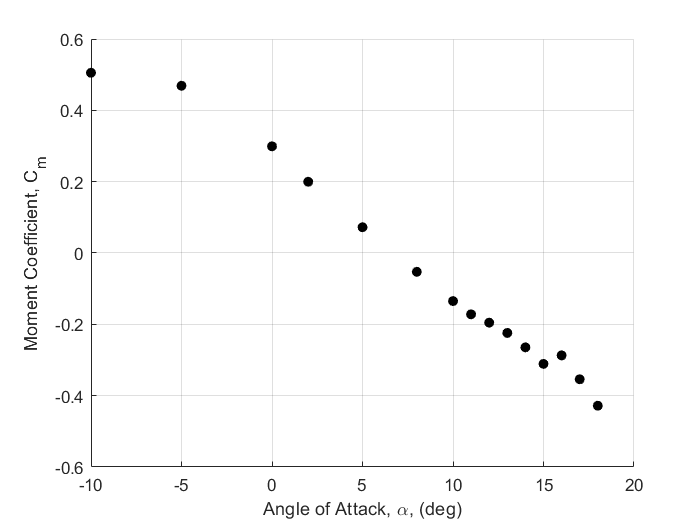


% Moment Curve graph
figure
scatter(AoA,Cm, 'filled','black')
xlabel('Angle of Attack, \alpha, (deg)')
ylabel('Moment Coefficient, C_{m}')
grid on


% From linear curve fit,
Cma = -0.035

Cma = -0.0400

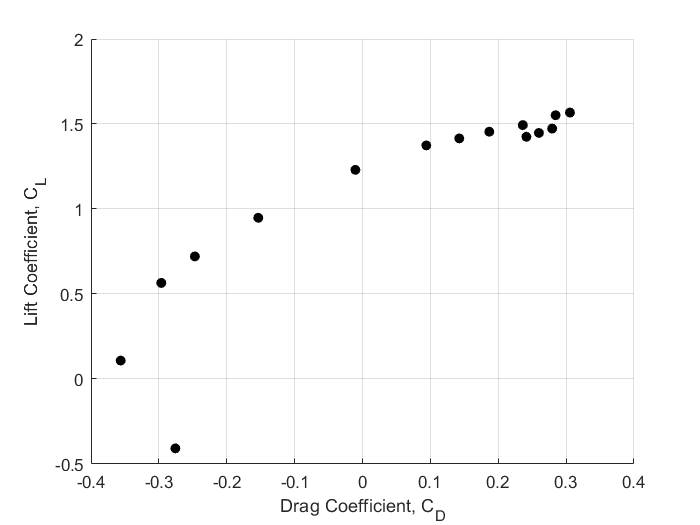


% Drag Polar
figure
scatter(CD,CL,'filled','black')
xlabel('Drag Coefficient, C_{D}')
ylabel('Lift Coefficient, C_{L}')
grid on